# Analysis

## Import saved dataset

clear all;
% eeglab; close;
filepath = 'C:\\Users\\anhtn\\OneDrive - PennO365\\Documents\\GitHub\\analysis\\Datasets\\';
trial = '001-AOE';
filename = [trial '-preprocessed.set']; % manually type to select dataset
EEG = pop_loadset('filename', filename, 'filepath', filepath);

pop_loadset(): loading file C:\Users\anhtn\OneDrive - PennO365\Documents\GitHub\analysis\Datasets\001-AOE-preprocessed.set ...
eeg_checkset: recomputing the ICA activation matrix ...


plot_folder = ['plot-' trial '\\' ];

###  Extract epochs and select C3, C4 electrodes

RH_cluster = {'C4', 'FC2', 'FC6', 'F4'};
LH_cluster = {'C3', 'FC5', 'FC1', 'F3'};
all_elec = [RH_cluster LH_cluster];

elec_plot = {all_elec}; % plot PSD of EEG at all relevant electrodes
%elec_plt = {RH_cluster, LH_cluster} % plot PSD of EEG at RH and LH cluster

freqs_array = [6,8,10,12,20,30];

markerVal_string = ["10" "11" "12" "13" "14" "15" "16" "17"...
    "20" "21" "22" "23" "24" "25" "26" "27" ...
    "30" "31" "32" "33" "34" "35" "36" "37" ...
    "40" "41" "42" "43" "44" "45" "46" "47"];

markerLabel = ["human-left", "human-right", "robot-left", "robot-right"];

### Baseline epochs and plot PSD of baseline

% base_tlen = [1 5];
% 
% cond_plot_spectra(EEG, {'1000'}, base_tlen, freqs_array, elec_plot, "baseline")


## Stim epochs

### Plot power spectrum of conditions

events_cell = 1×8 cell array
    {[10]}    {[11]}    {[12]}    {[13]}    {[14]}    {[15]}    {[16]}    {[17]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


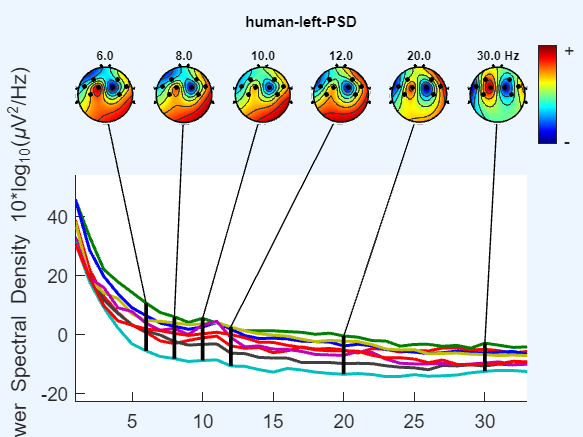

events_cell = 1×8 cell array
    {[20]}    {[21]}    {[22]}    {[23]}    {[24]}    {[25]}    {[26]}    {[27]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


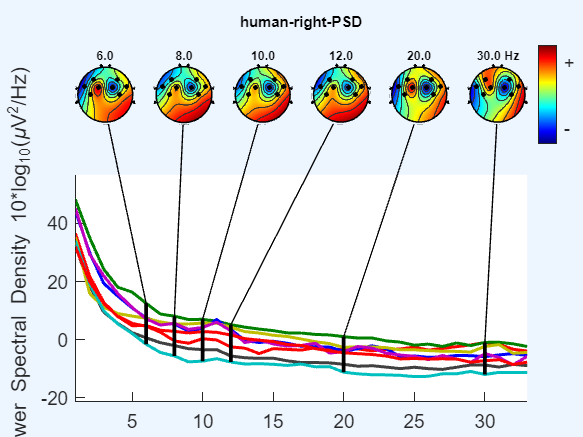

events_cell = 1×8 cell array
    {[30]}    {[31]}    {[32]}    {[33]}    {[34]}    {[35]}    {[36]}    {[37]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


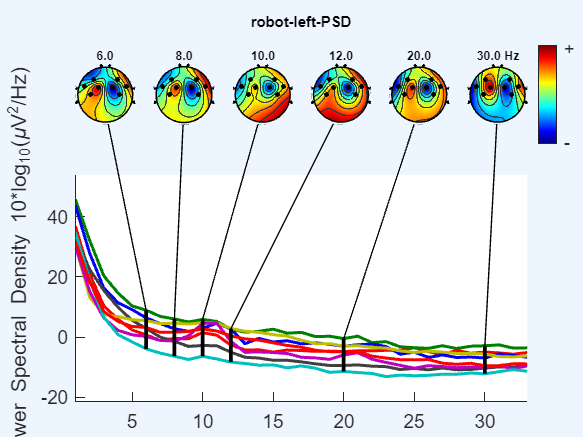

events_cell = 1×8 cell array
    {[40]}    {[41]}    {[42]}    {[43]}    {[44]}    {[45]}    {[46]}    {[47]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


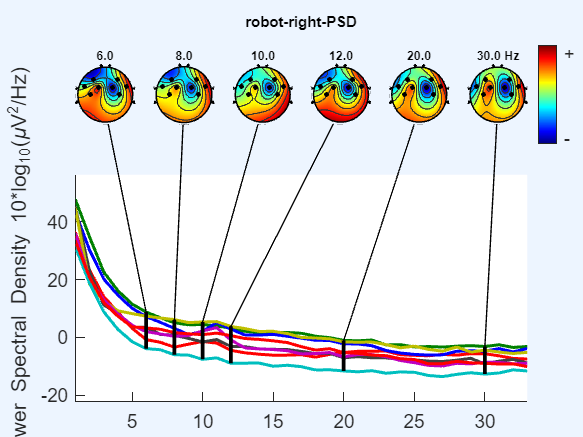

stim_epoch = [0 4];
markerVal_num = [10  11  12  13  14  15  16  17 20  21  22  23  24  25  26  27  30  31  32  33  34  35  36  37  40  41  42  43  44  45  46  47];

for i = 1:4
    cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_epoch, ...
        freqs_array, elec_plot, markerLabel(i)+"-PSD", [filepath plot_folder]);
end

### Time-freq analysis

Processing using C3 and C4 for now. Can look at ICA component later

events_cell = 1×8 cell array
    {[10]}    {[11]}    {[12]}    {[13]}    {[14]}    {[15]}    {[16]}    {[17]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

Note: Add output variables to command line call in history to
      retrieve results and use the tftopo function to replot them

ans =

  0×0 empty char array

Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835.938 ms) wide.
Estimating 27 linear-spaced frequencies from 4.0 Hz to 30.0 Hz.
Processing time point (of 200): 10 20 30 40 50 60 70 80 90 100 110 120
 130 140 150 160 170 180 190 200
Computing the mean baseline spectrum
Note: Add out

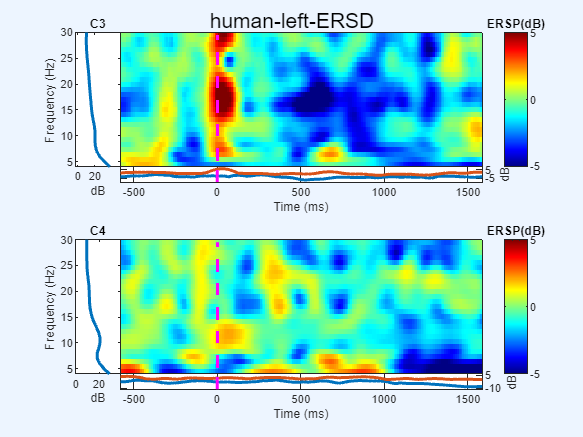

events_cell = 1×8 cell array
    {[20]}    {[21]}    {[22]}    {[23]}    {[24]}    {[25]}    {[26]}    {[27]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

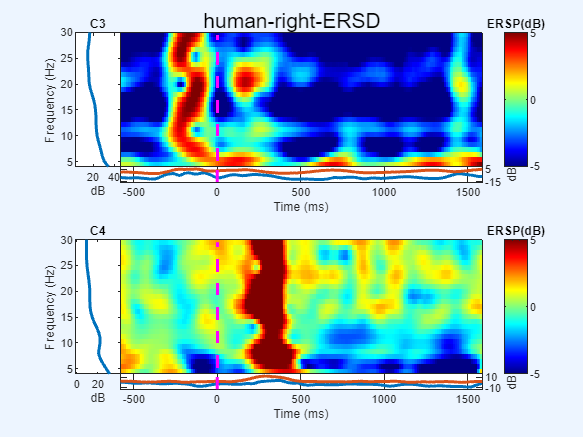

events_cell = 1×8 cell array
    {[30]}    {[31]}    {[32]}    {[33]}    {[34]}    {[35]}    {[36]}    {[37]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

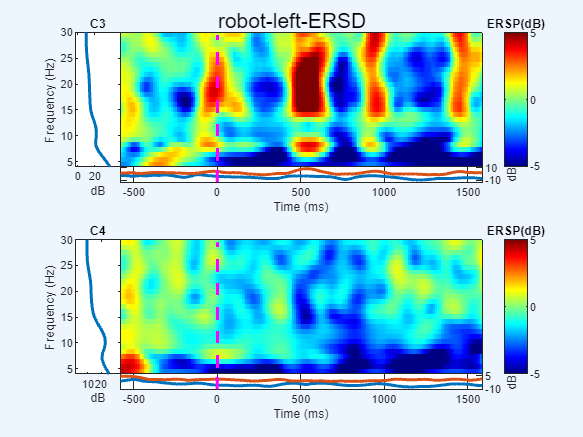

events_cell = 1×8 cell array
    {[40]}    {[41]}    {[42]}    {[43]}    {[44]}    {[45]}    {[46]}    {[47]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

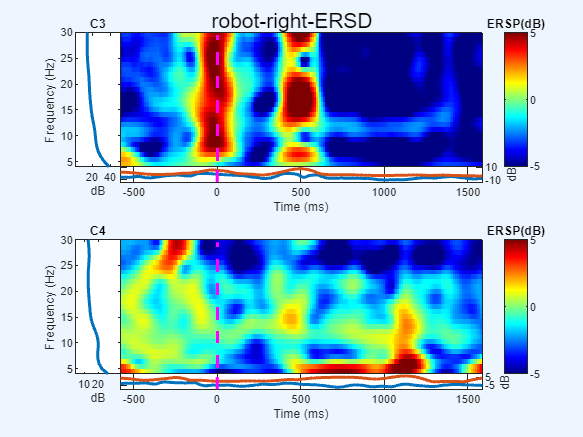

stim_tlen = [-1 3];
ersp_color_lim = 5;
alpha = 0;
for i = 1:4
    cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'}, ersp_color_lim, alpha, markerLabel(i) + "-ERSD", [filepath plot_folder]);
end

Hypotheses?

events_cell = 1×8 cell array
    {[10]}    {[11]}    {[12]}    {[13]}    {[14]}    {[15]}    {[16]}    {[17]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

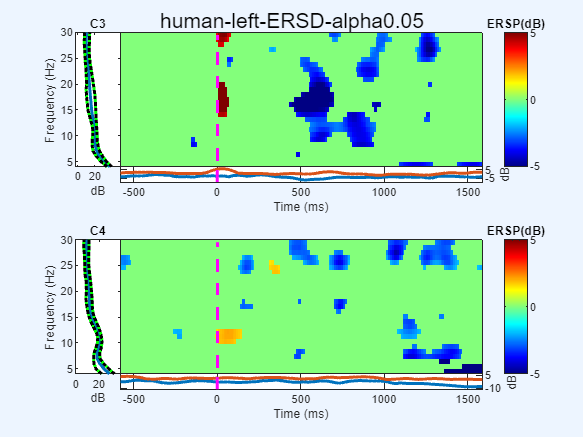

events_cell = 1×8 cell array
    {[20]}    {[21]}    {[22]}    {[23]}    {[24]}    {[25]}    {[26]}    {[27]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

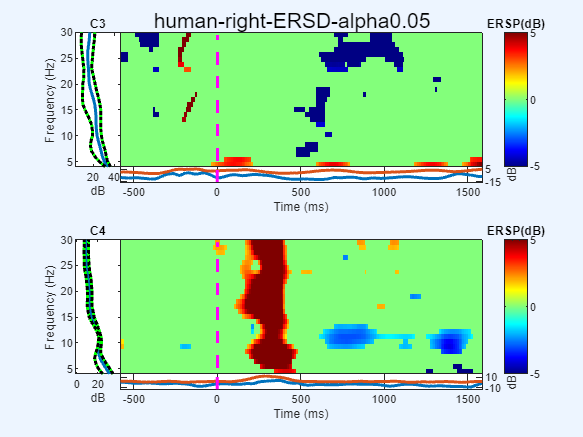

events_cell = 1×8 cell array
    {[30]}    {[31]}    {[32]}    {[33]}    {[34]}    {[35]}    {[36]}    {[37]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

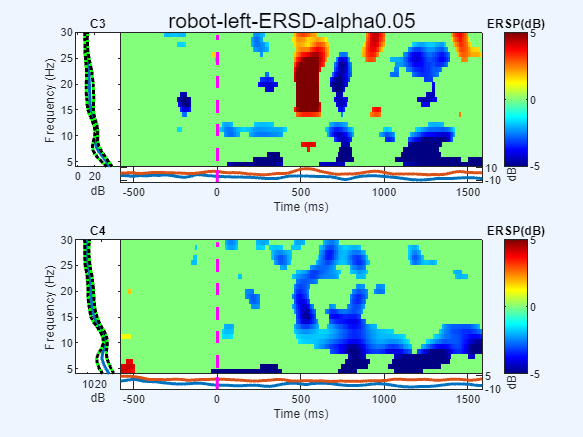

events_cell = 1×8 cell array
    {[40]}    {[41]}    {[42]}    {[43]}    {[44]}    {[45]}    {[46]}    {[47]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

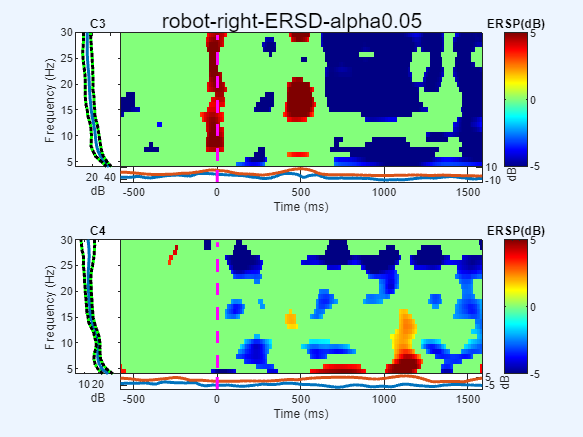

alpha = 0.05;
for i = 1:4
    cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), stim_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'},ersp_color_lim, alpha, markerLabel(i) + "-ERSD-alpha0.05",[filepath plot_folder]);
end

## Execution epochs

markerVal_num = [110  111  112  113  114  115  116  117 120  121  122  123  124  125  126  27  130  131  132  133  134  135  136  137  140  141  142  143  144  145  146  147];
exe_epoch = [0 4];

### Plot power spectrum of conditions

events_cell = 1×8 cell array
    {[110]}    {[111]}    {[112]}    {[113]}    {[114]}    {[115]}    {[116]}    {[117]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


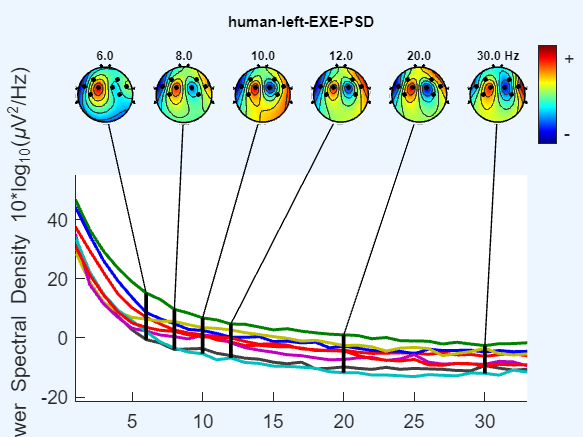

events_cell = 1×8 cell array
    {[120]}    {[121]}    {[122]}    {[123]}    {[124]}    {[125]}    {[126]}    {[27]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


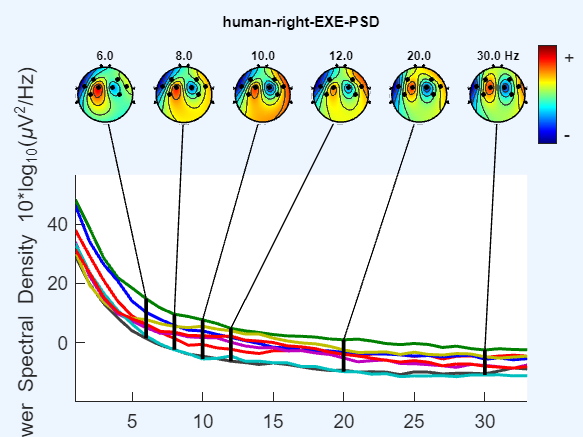

events_cell = 1×8 cell array
    {[130]}    {[131]}    {[132]}    {[133]}    {[134]}    {[135]}    {[136]}    {[137]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


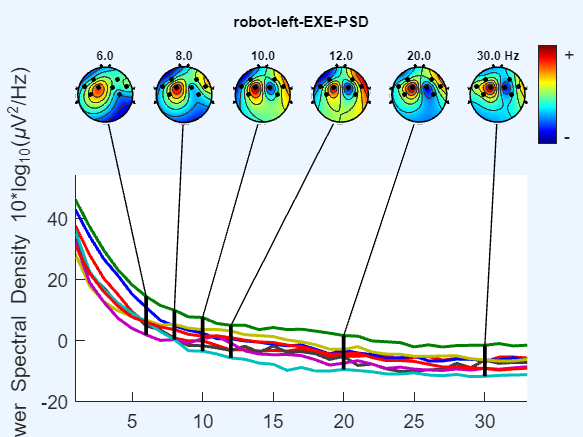

events_cell = 1×8 cell array
    {[140]}    {[141]}    {[142]}    {[143]}    {[144]}    {[145]}    {[146]}    {[147]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 24 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
pop_spectopo(): selecting time range   0.00 ms to 4000.00 ms (points 1 to 512)
Note: duplicate 'key', 'val' parameter(s), keeping the last one(s)
Computing spectra (window length 128; fft length: 128; overlap 0):
........
Plotting scalp distributions: ......
Click on each trace for channel/component index


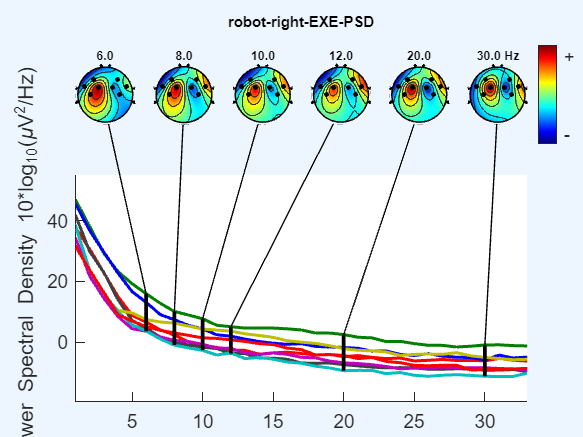

for i = 1:4
    cond_plot_spectra(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), exe_epoch, ...
        freqs_array, elec_plot, markerLabel(i)+"-EXE-PSD", [filepath plot_folder]);
end

### Time-freq analysis

Processing using C3 and C4 for now. Can look at ICA component later

events_cell = 1×8 cell array
    {[110]}    {[111]}    {[112]}    {[113]}    {[114]}    {[115]}    {[116]}    {[117]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

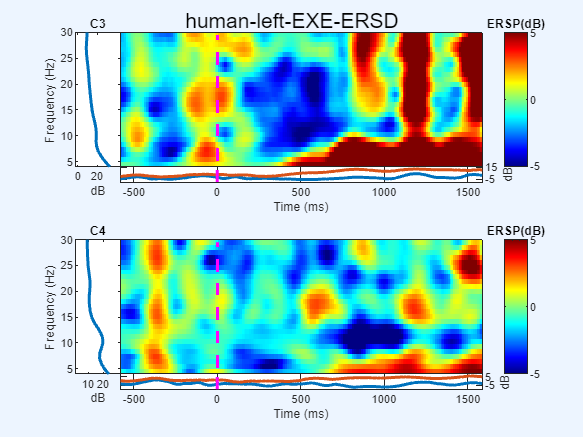

events_cell = 1×8 cell array
    {[120]}    {[121]}    {[122]}    {[123]}    {[124]}    {[125]}    {[126]}    {[27]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

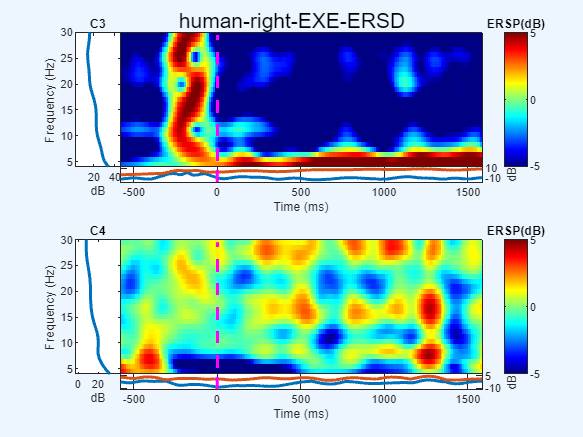

events_cell = 1×8 cell array
    {[130]}    {[131]}    {[132]}    {[133]}    {[134]}    {[135]}    {[136]}    {[137]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

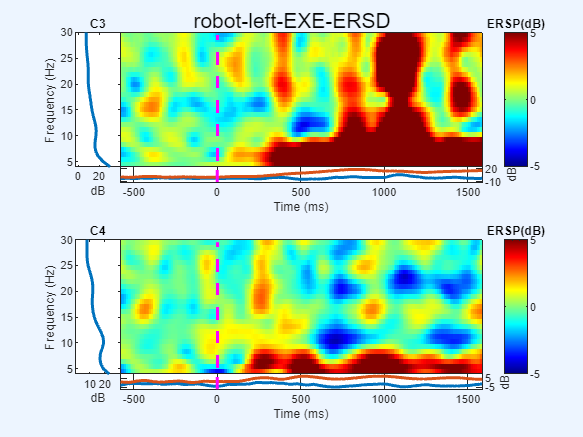

events_cell = 1×8 cell array
    {[140]}    {[141]}    {[142]}    {[143]}    {[144]}    {[145]}    {[146]}    {[147]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200 time points (-582.0 to 1582.0 ms)
Finding closest points for time variable
Time values for time/freq decomposition is not perfectly uniformly distributed
The window size used is 107 samples (835

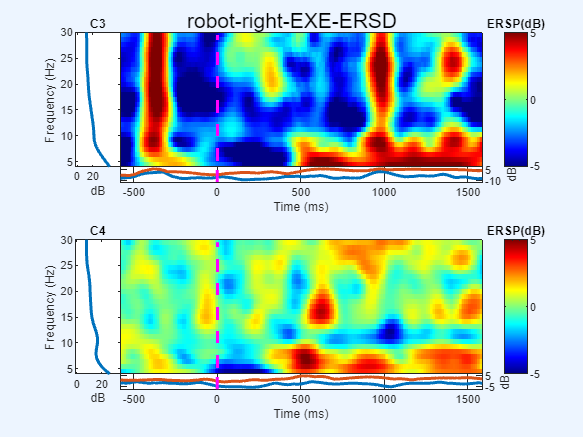

exe_tlen = [-1 3];
ersp_color_lim = 5;
alpha = 0;
for i = 1:4
    cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), exe_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'}, ersp_color_lim, alpha, markerLabel(i) + "-EXE-ERSD", [filepath plot_folder]);
end

Hypotheses?

events_cell = 1×8 cell array
    {[110]}    {[111]}    {[112]}    {[113]}    {[114]}    {[115]}    {[116]}    {[117]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

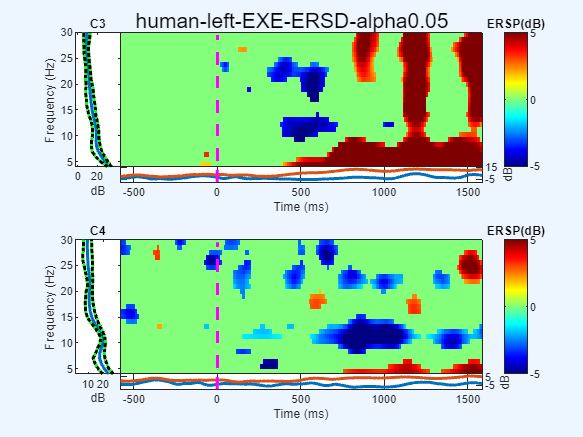

events_cell = 1×8 cell array
    {[120]}    {[121]}    {[122]}    {[123]}    {[124]}    {[125]}    {[126]}    {[27]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

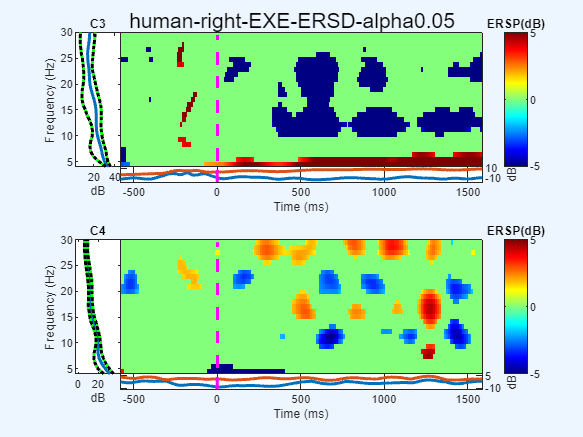

events_cell = 1×8 cell array
    {[130]}    {[131]}    {[132]}    {[133]}    {[134]}    {[135]}    {[136]}    {[137]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

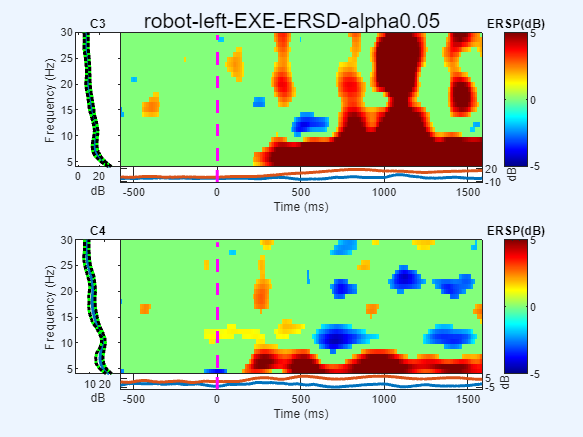

events_cell = 1×8 cell array
    {[140]}    {[141]}    {[142]}    {[143]}    {[144]}    {[145]}    {[146]}    {[147]}


pop_epoch():24 epochs selected
Epoching...
pop_epoch():24 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity
pop_rmbase(): Removing baseline...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing 31 channel(s)...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Permutation analysis will use data in (pre-0) baseline subwindows only.
Computing Event-Related Spectral Perturbation (ERSP) and
  Inter-Trial Phase Coherence (ITC) images based on 24 trials
  of 385 frames sampled at 128 Hz.
Each trial contains samples from -1000 ms before to
  2000 ms after the timelocking event.
Only significant values (permutation statistics p<0.05) will be colored;
  non-significant values will be plotted in green
  Image frequency direction: normal
Using 3 cycles at lowest frequency to 11.25 at highest.
Generating 200

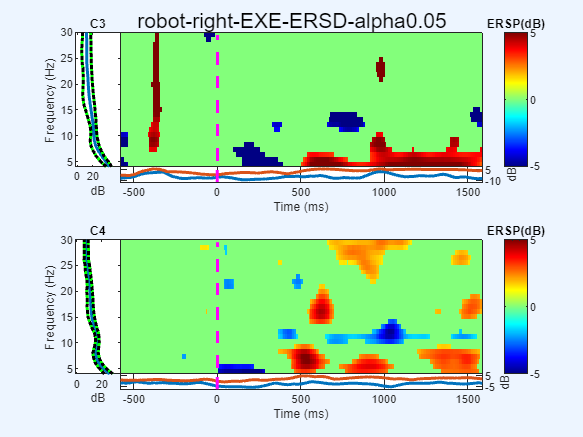

alpha = 0.05;
for i = 1:4
    cond_ersp(EEG, num2cell(markerVal_num((i-1)*8+1:i*8)), exe_tlen, ...
        [-1 2], [4 30], {'C3', 'C4'},ersp_color_lim, alpha, markerLabel(i) + "-EXE-ERSD-alpha0.05",[filepath plot_folder]);
end

function cond_ersp(EEG, events_cell, tlen, sub_epoch_len, freqs, channels, erspmax, alpha, plottitle, filepath)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);

    if length(channels) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', channels);
        if alpha ~= 0
            figure; pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
            'freqs', freqs, 'plotitc', 'off', 'erspmax', erspmax, 'alpha', alpha)
        else
            figure; pop_newtimef(EEG_cond_chan, 1, 1, sub_epoch_len*1000, [3 0.5], ...
            'freqs', freqs, 'plotitc', 'off', 'erspmax', erspmax)
        end
    
    elseif length(channels) == 2
        EEG_cond_chan1 = pop_select( EEG_cond_epoch, 'channel', channels(1));
        EEG_cond_chan2 = pop_select( EEG_cond_epoch, 'channel', channels(2));

        if alpha ~= 0
            figure; sgtitle(plottitle)
            subplot(2,1,1); pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'erspmax', erspmax, 'alpha', alpha)
            title(string(channels(1)))
            subplot(2,1,2); pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'erspmax', erspmax, 'alpha', alpha)
            title(string(channels(2)))
        else 
            figure; sgtitle(plottitle)
            subplot(2,1,1); pop_newtimef(EEG_cond_chan1, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'erspmax', erspmax)
            title(string(channels(1)))
            subplot(2,1,2); pop_newtimef(EEG_cond_chan2, 1, 1, sub_epoch_len*1000, [3 0.5], ...
                'freqs', freqs, 'plotitc', 'off', 'erspmax', erspmax)
            title(string(channels(2)))
        end
    end
    savefig(fullfile(filepath, plottitle+".fig"));
end


function cond_plot_spectra(EEG, events_cell, tlen, freqs, chanlocs, plottitle, filepath)
    EEG_cond_epoch = cond_epoch(EEG, events_cell, tlen);
    
    if length(chanlocs) == 1
        EEG_cond_chan = pop_select( EEG_cond_epoch, 'channel', chanlocs{1});
        figure; title(plottitle);
        pop_spectopo(EEG_cond_chan, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on');

    elseif length(chanlocs) == 2
        EEG_cond_RH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1});
        EEG_cond_LH = pop_select( EEG_cond_epoch, 'channel',chanlocs{1}); 
        figure; sgtitle(plottitle);
        subplot(211); pop_spectopo(EEG_cond_RH, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on');
        subplot(212); pop_spectopo(EEG_cond_LH, 1, tlen*1000, 'EEG',...
            'freq', freqs, 'chanlocs', EEG.chaninfo, 'electrodes', 'on');
    end
    savefig(fullfile(filepath, plottitle+".fig"));

end

function OUTEEG = cond_epoch(EEG, events_cell, tlen)
    events_cell
    EEG_epoch = pop_epoch(EEG, events_cell, tlen);
    OUTEEG = pop_rmbase(EEG_epoch, [0 0.5]*1000);

end




















